# Retreive Ball Cups

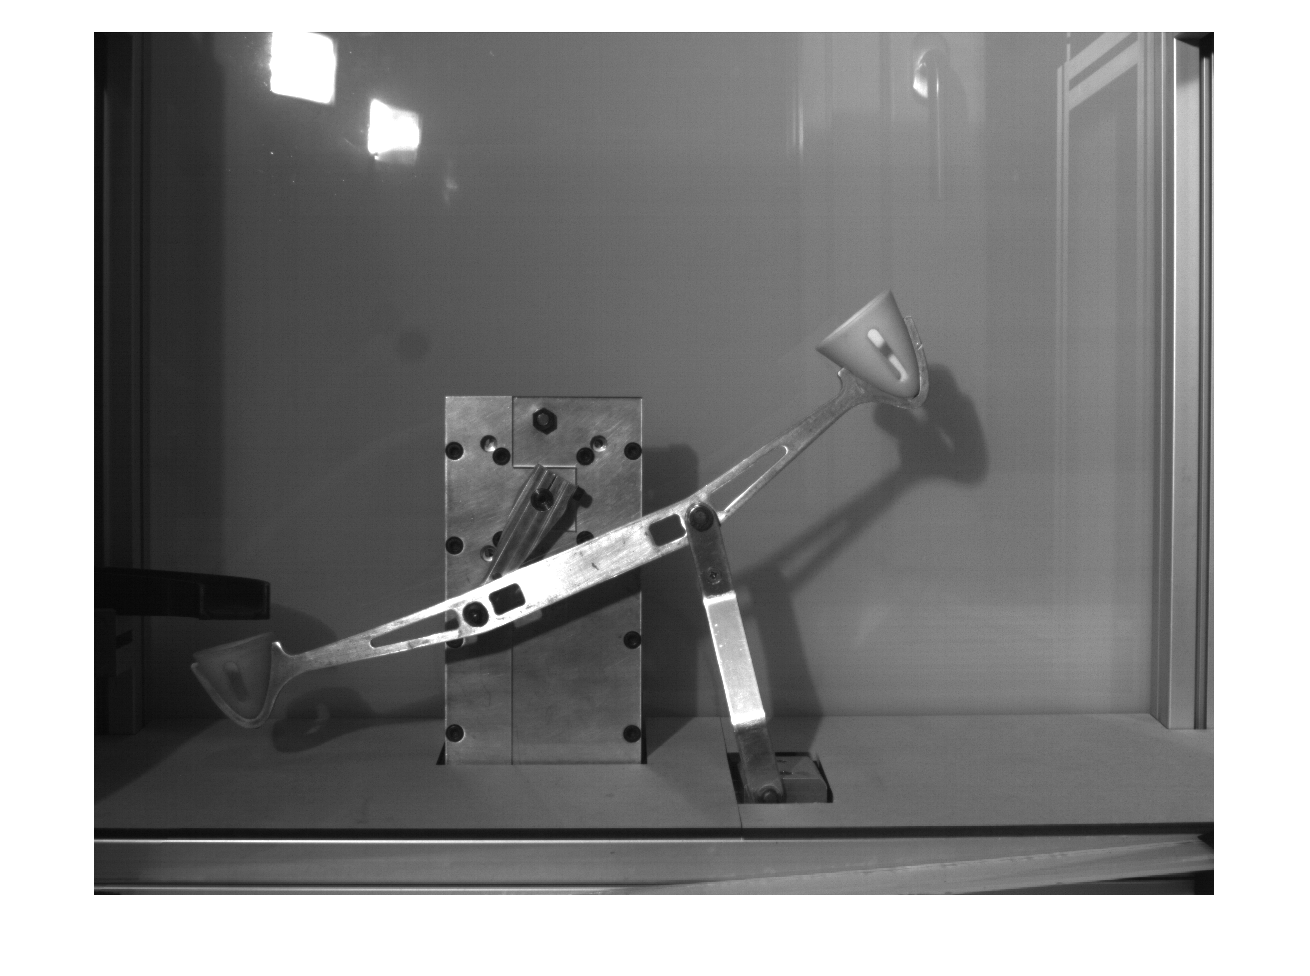

frame = video_data(100,:,:);
frame = squeeze(frame);

figure, imshow(frame)

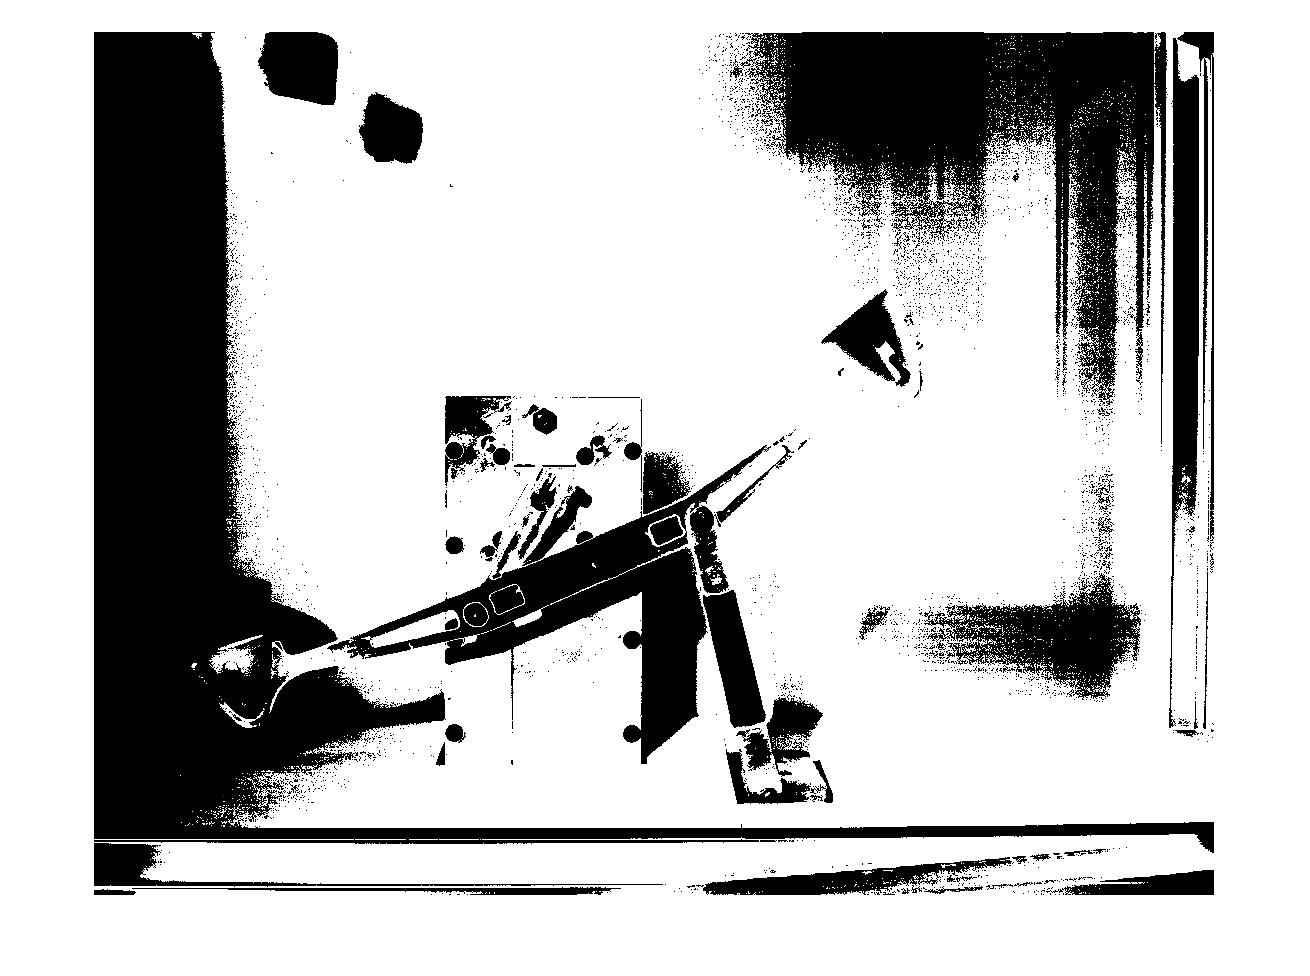


frame(frame>130) = 0;
%frame(frame<30) = 0;
frame = imbinarize(frame);

figure, imshow(frame);

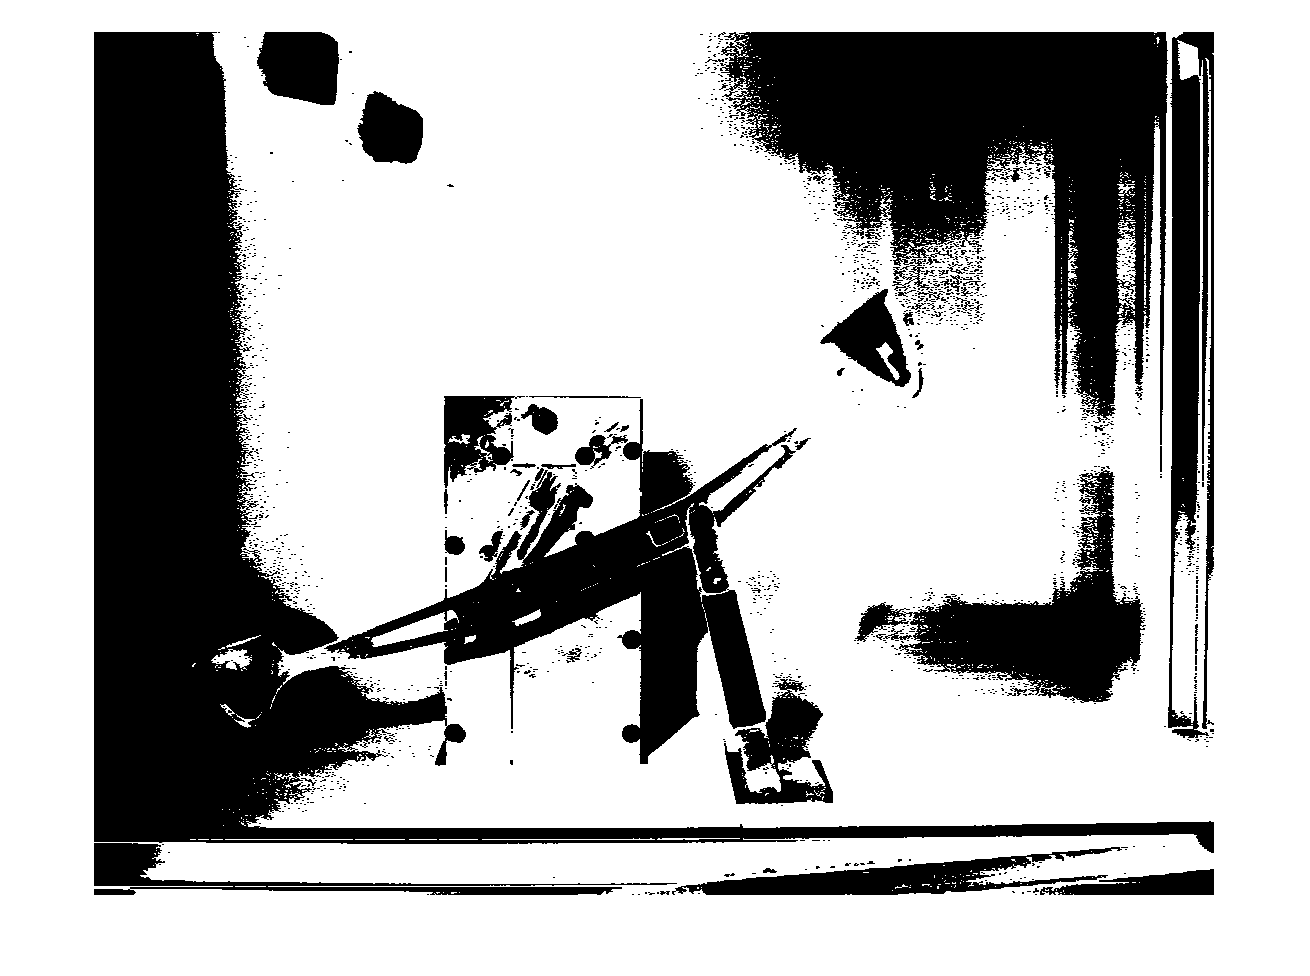

grayImage = imerode(frame, strel('rectangle', [2, 4]));
figure, imshow(grayImage);

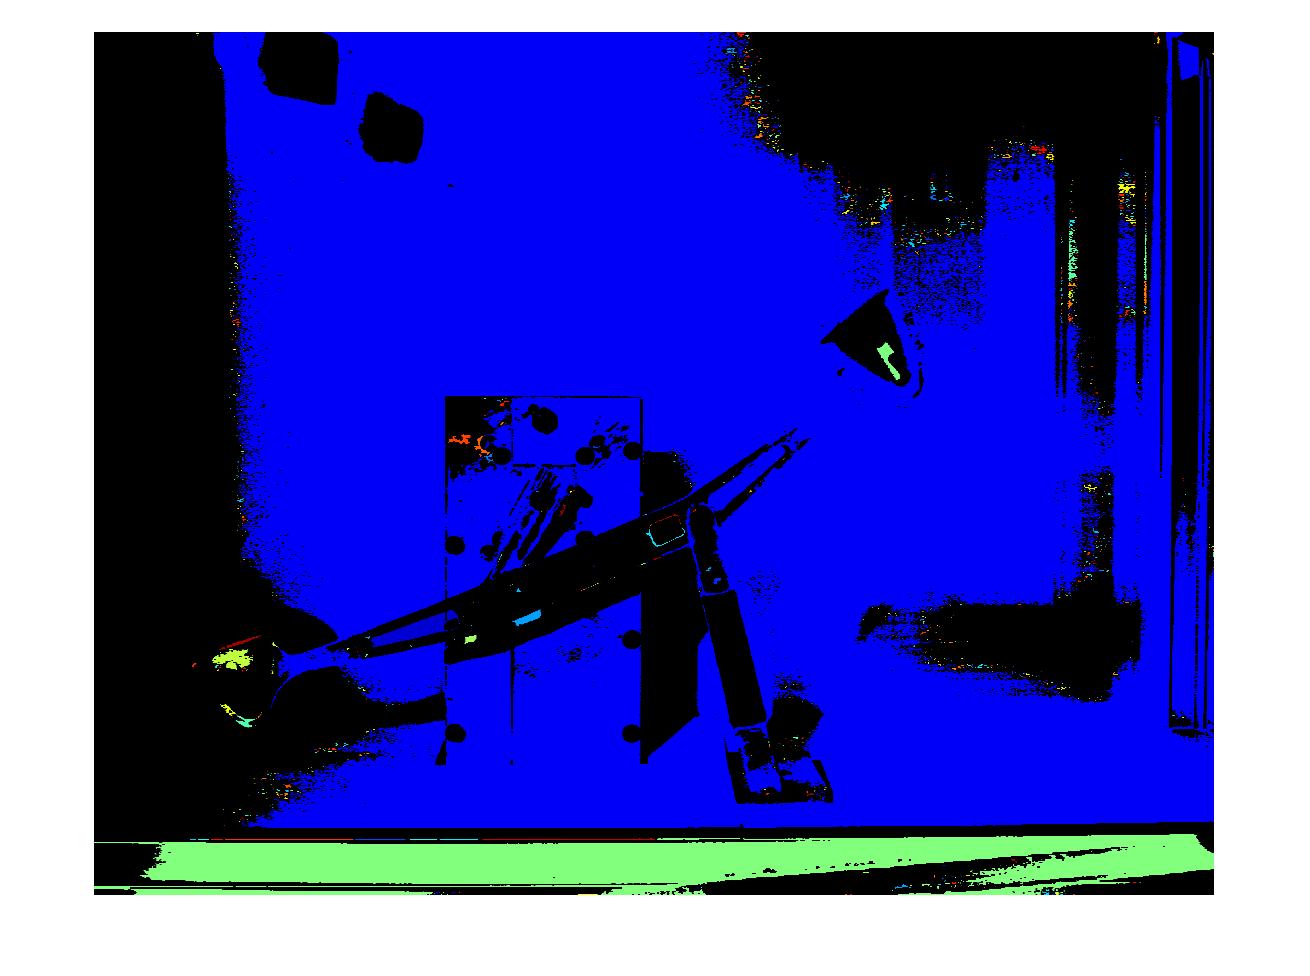


labeledImage = bwlabel(grayImage);
rgbLabeledImage = label2rgb(labeledImage, 'jet', 'k', 'shuffle'); % 'jet' colormap, 'k' background
figure, imshow(rgbLabeledImage);

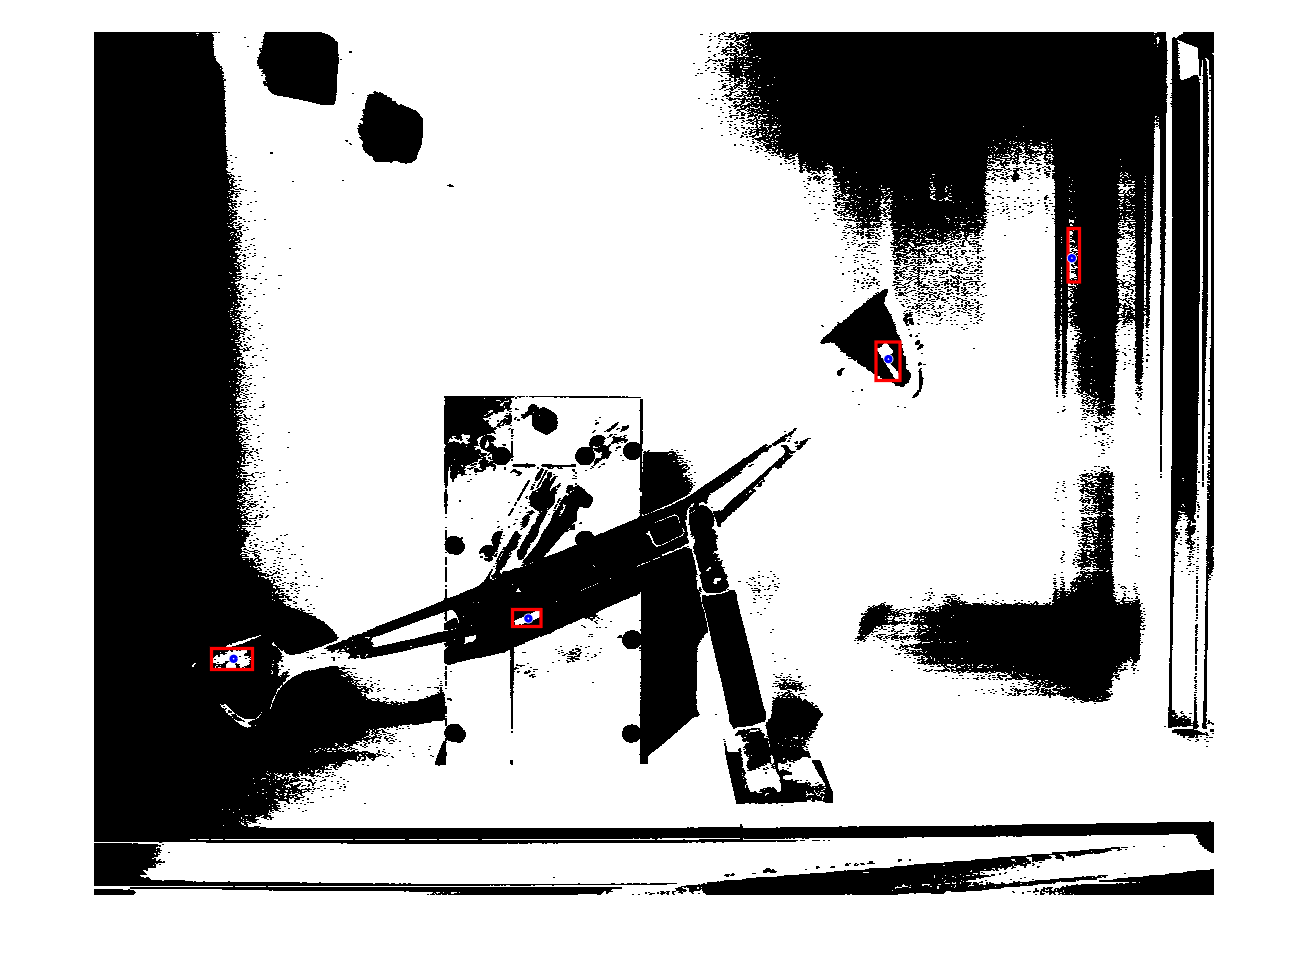



% Measure properties of connected components
props = regionprops('table',labeledImage, 'BoundingBox', 'Orientation', 'Centroid', 'Area');

% Debug and visualize the results
imshow(grayImage);
hold on;

filteredProps = props(props.Area > 500 & props.Area < 3000, :);
centroids = filteredProps.Centroid;
boundingBoxes = filteredProps.BoundingBox;
for k = 1:height(filteredProps)
    rectangle('Position', boundingBoxes(k, :), 'EdgeColor', 'r', 'LineWidth', 2);
end
viscircles(centroids, ones(size(centroids, 1), 1) * 5, 'Color', 'b');

hold off;

disp('Centroids of rectangles with area > 20:');

Centroids of rectangles with area > 20:


disp(centroids);

   1.0e+03 *

    0.2797    1.2541
    0.8693    1.1735
    1.5893    0.6547
    1.9563    0.4529

